**Explicit MP****C**

Let's now return to the simple double integrator system of our first example.  Assuming a sampling time of 1 second, the system dynamics are given by 


$$x(k+1) = \pmatrix{1 & 1 \cr 0 & 1}x(k)+\pmatrix{0 \cr 1} u(k)$$



$$y(k) = \pmatrix{1 & 0}x(k)$$


 Once again, let's use the objective function 


$$J = \sum_{k=0}^1\left(y(k)^2+\frac{1}{10}u(k)^2\right)+x(2)^T\pmatrix{1 & 0 \cr 0 & 1}x(2)$$


and constrain the control inputs such that 


$$-1\leq u(k) \leq 1$$


Build the basic matrices for the problem.

A = [1 1;0 1];
B = [0;1];
R = 1/10;
Q = [1 0;0 0];  %Using knowledge of C
P = eye(2);
Qbar = blkdiag(Q,P);
Rbar = blkdiag(R,R);
Sbar = [B zeros(2,1);A*B B];
Tbar = [A;A^2];

Now convert into the form used by QP.

H = 2*(Rbar+Sbar'*Qbar*Sbar)

H =     4.2000    2.0000
    2.0000    2.2000


F = (2*Tbar'*Qbar*Sbar)'

F =      2     6
     0     2


G = [eye(2);-eye(2)]

G =      1     0
     0     1
    -1     0
     0    -1


W = [1;1;1;1]

W =      1
     1
     1
     1


S = zeros(4,2)

S =      0     0
     0     0
     0     0
     0     0


**Explicit Solution**

For starters let me think about the possible active constraints:

- 
$$u_0 = u_1 = u_{max}$$


- 
$$u_0 = u_{max}$$


- 
$$u_1 = u_{max}$$


- 
$$u_0 = u_1 = u_{min}$$


- 
$$u_0 = u_{min}$$


- 
$$u_1 = u_{min}$$


- 
$$u_0 = u_{max}, u_1 = u_{min}$$


- 
$$u_0 = u_{min}, u_1 = u_{max}$$


I can now start tackling these one-by-one...

Set 1:

Gtild = G(1:2,:);
Wtild = W(1:2);
Stild = zeros(2);
region(1).E = inv(H)*(Gtild'*inv(Gtild*inv(H)*Gtild')*(Stild+Gtild*inv(H)*F)-F);
region(1).g = inv(H)*Gtild'*inv(Gtild*inv(H)*Gtild')*Wtild;
region(1).E

ans = 	1.0e+-15 *

   -0.0932   -0.3729
    0.0847    0.3390


region(1).g

ans =     1.0000
    1.0000


I guess I already knew the control, but nice to see that it made sense.  I will reset E1 to 0 to avoid numerical issues...

region(1).E = zeros(2);

What about the region? 

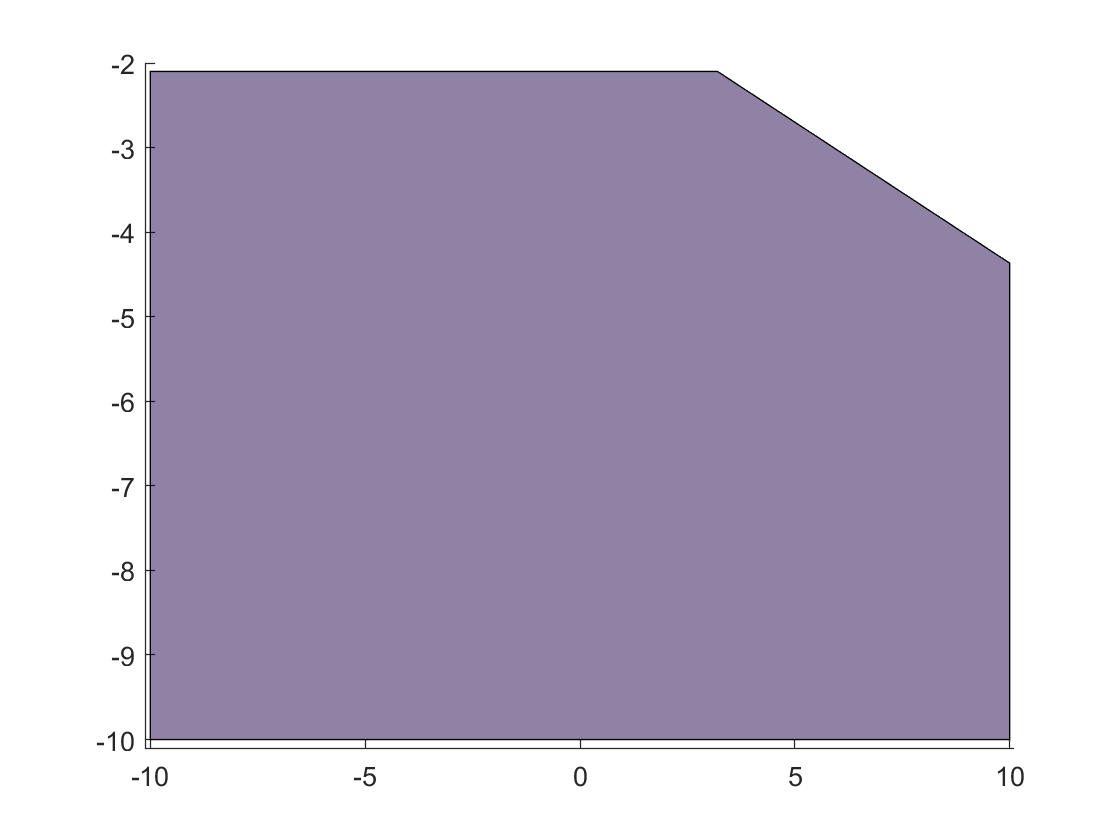

region(1).H = [G*region(1).E-S;inv(Gtild*inv(H)*Gtild')*(Stild+Gtild*inv(H)*F)];
region(1).K = [W-G*region(1).g;-inv(Gtild*inv(H)*Gtild')*Wtild];
lb = [-10;-10];
ub = [10,10];
figure
plotregion(-region(1).H,-region(1).K,lb,ub)
hold off

Set 2:

Gtild = G(1,:);
Wtild = W(1);
Stild = zeros(1,2);
region(2).E = inv(H)*(Gtild'*inv(Gtild*inv(H)*Gtild')*(Stild+Gtild*inv(H)*F)-F);
region(2).g = inv(H)*Gtild'*inv(Gtild*inv(H)*Gtild')*Wtild;

What about the region? 

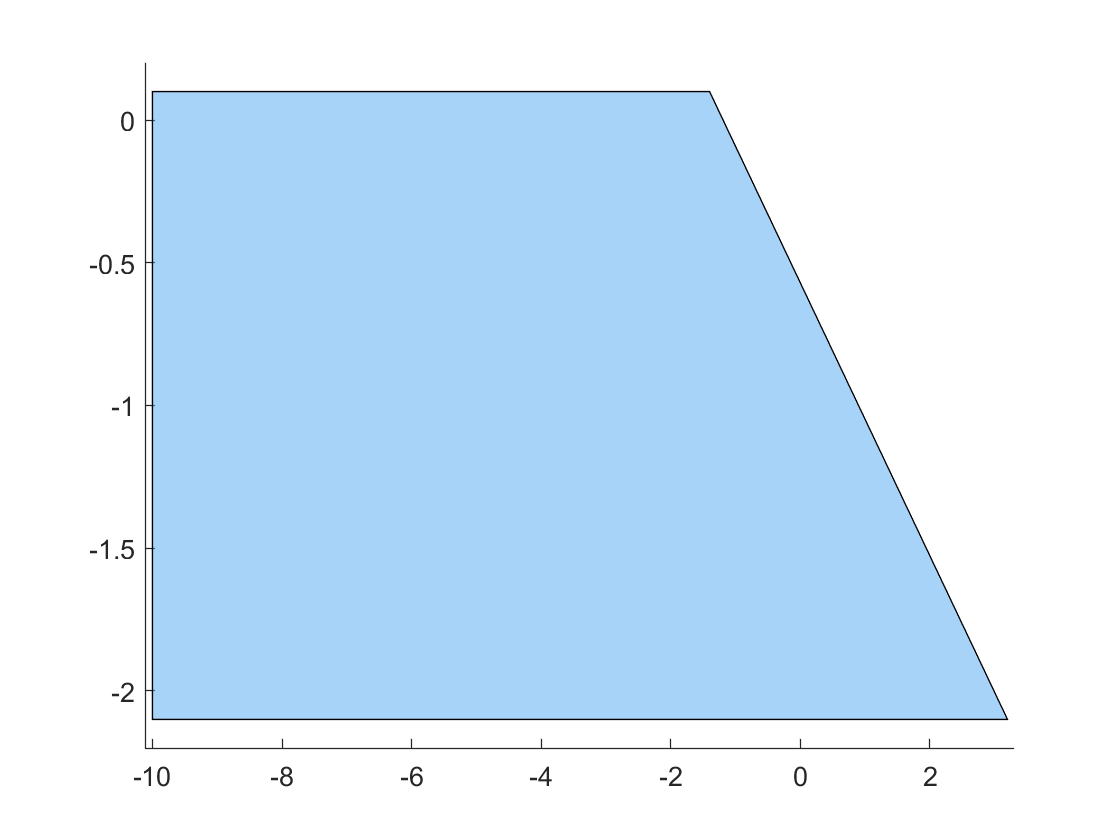

region(2).H = [G*region(2).E-S;inv(Gtild*inv(H)*Gtild')*(Stild+Gtild*inv(H)*F)];
region(2).K = [W-G*region(2).g;-inv(Gtild*inv(H)*Gtild')*Wtild];
figure
plotregion(-region(2).H,-region(2).K,lb,ub)

**Note:**  These two regions give exactly the same $u_0$ - they would be merged in an implementation.

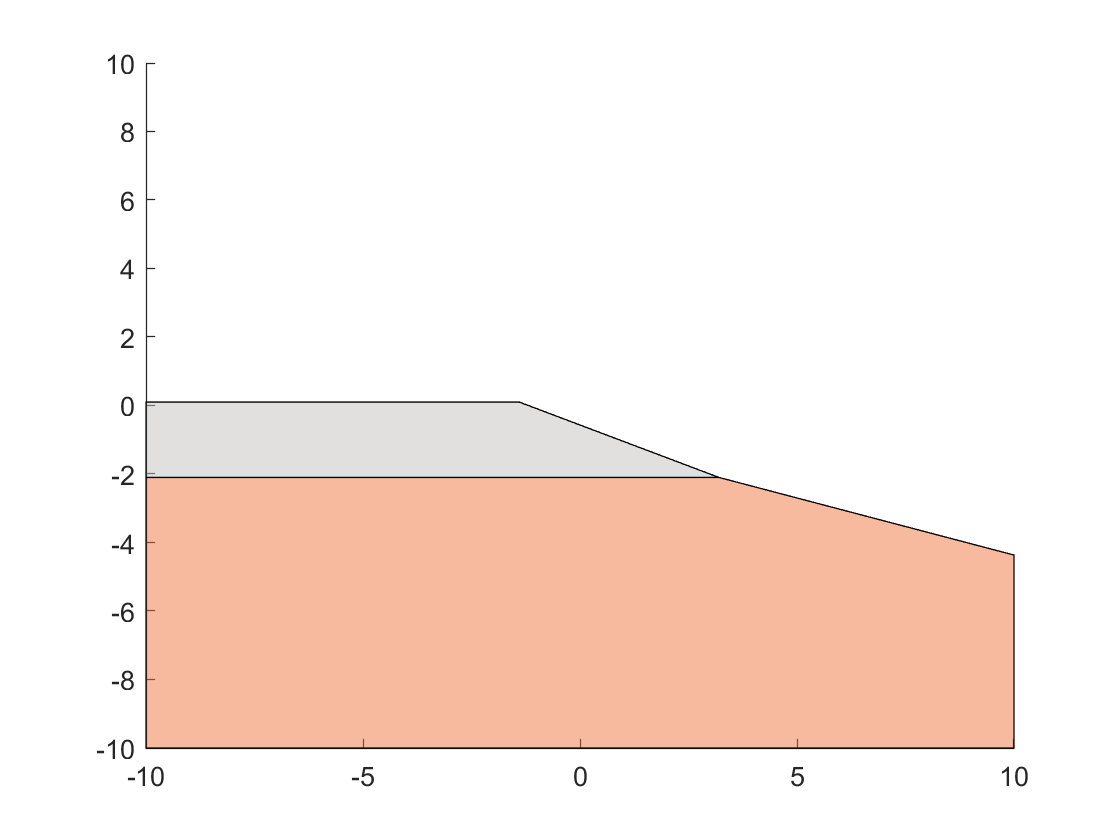

figure
plotregion(-region(1).H,-region(1).K,lb,ub)
plotregion(-region(2).H,-region(2).K,lb,ub)
ylim([lb(1),ub(1)])
xlim([lb(1),ub(1)])

*Sanity Check*

Let's show that the explicit solution is identical to the QP solution.  Based on Region 2, I think I can pick $x = [-2,0]^T$.

X = [-2;0];
z_explicit = region(2).E*X+region(2).g

z_explicit =     1.0000
   -0.9091


f = F*X;
[z_online,~,~,~,lam] = quadprog(H,f,G,W+S*X,[],[],[],[],[],options);
z_online

z_online =     1.0000
   -0.9091


Set 3:

Gtild = G(2,:);
Wtild = W(2);
Stild = zeros(1);
region(3).E = inv(H)*(Gtild'*inv(Gtild*inv(H)*Gtild')*(Stild+Gtild*inv(H)*F)-F);
region(3).g = inv(H)*Gtild'*inv(Gtild*inv(H)*Gtild')*Wtild;

What about the region? 

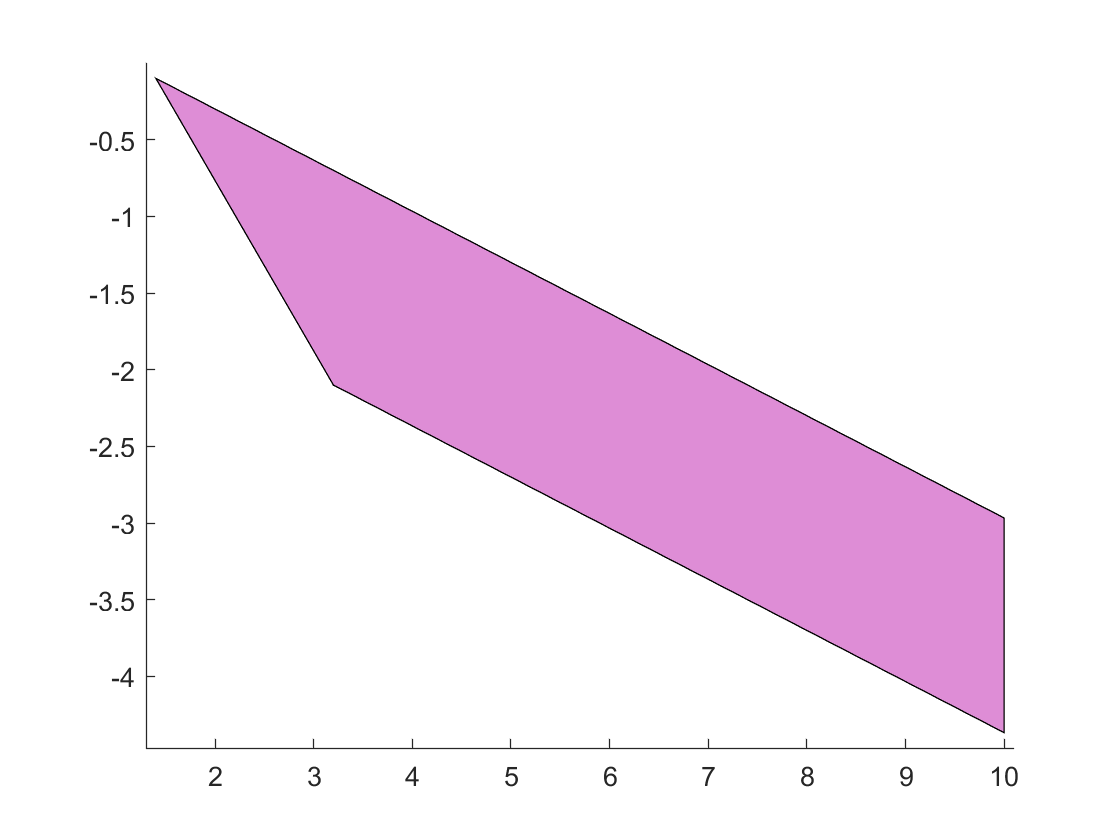

region(3).H = [G*region(3).E-S;inv(Gtild*inv(H)*Gtild')*(Stild+Gtild*inv(H)*F)];
region(3).K = [W-G*region(3).g;-inv(Gtild*inv(H)*Gtild')*Wtild];
lb = [-10;-10];
ub = [10,10];
figure
plotregion(-region(3).H,-region(3).K,lb,ub)
hold off

*Sanity Check*

Let's show that the explicit solution is identical to the QP solution.  Based on Region 3, I think I can pick $x = [4,-1.5]^T$.

X = [4;-1.5];
z_explicit = region(3).E*X+region(3).g

z_explicit =    -0.2381
    1.0000


f = F*X;
[z_online,~,~,~,lam] = quadprog(H,f,G,W+S*X,[],[],[],[],[],options);
z_online

z_online =    -0.2381
    1.0000


Set 4:

Gtild = G(3:4,:);
Wtild = W(3:4);
Stild = zeros(2);
region(4).E = inv(H)*(Gtild'*inv(Gtild*inv(H)*Gtild')*(Stild+Gtild*inv(H)*F)-F);
region(4).g = inv(H)*Gtild'*inv(Gtild*inv(H)*Gtild')*Wtild;

I guess I already knew the control, but nice to see that it made sense.  I will reset region(4).E to 0 to avoid numerical issues...

region(4).E = zeros(2);

What about the region? 

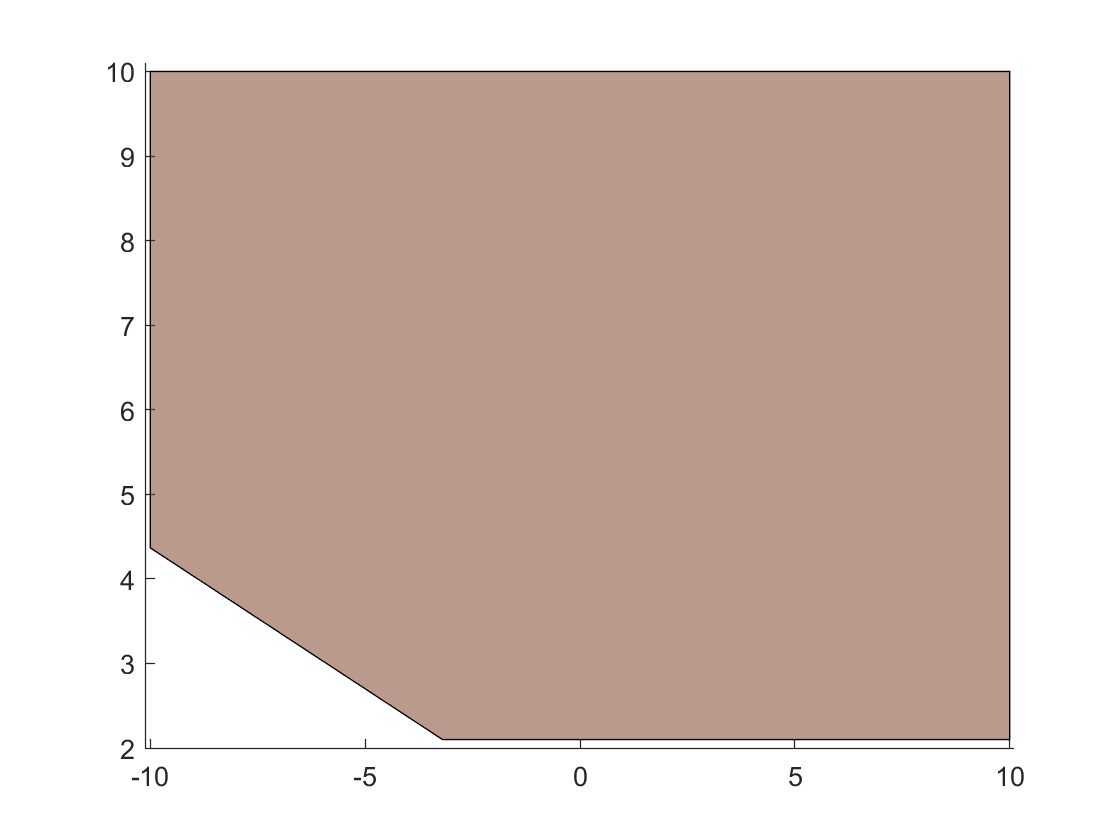

region(4).H = [G*region(4).E-S;inv(Gtild*inv(H)*Gtild')*(Stild+Gtild*inv(H)*F)];
region(4).K = [W-G*region(4).g;-inv(Gtild*inv(H)*Gtild')*Wtild];
lb = [-10;-10];
ub = [10,10];
figure
plotregion(-region(4).H,-region(4).K,lb,ub)
hold off

Set 5:

Gtild = G(3,:);
Wtild = W(3);
Stild = zeros(1);
region(5).E = inv(H)*(Gtild'*inv(Gtild*inv(H)*Gtild')*(Stild+Gtild*inv(H)*F)-F);
region(5).g = inv(H)*Gtild'*inv(Gtild*inv(H)*Gtild')*Wtild;

What about the region? 

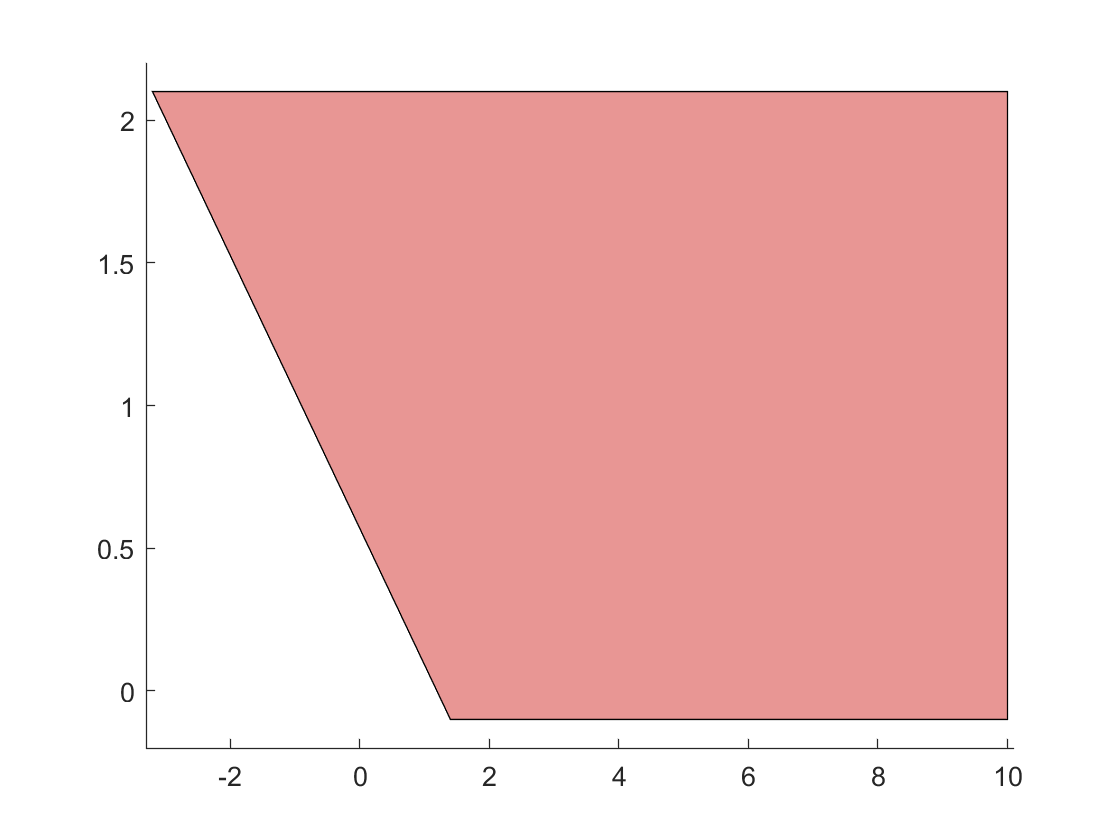

region(5).H = [G*region(5).E-S;inv(Gtild*inv(H)*Gtild')*(Stild+Gtild*inv(H)*F)];
region(5).K = [W-G*region(5).g;-inv(Gtild*inv(H)*Gtild')*Wtild];
lb = [-10;-10];
ub = [10,10];
figure
plotregion(-region(5).H,-region(5).K,lb,ub)
hold off

Set 6:

Gtild = G(4,:);
Wtild = W(4);
Stild = zeros(1);
region(6).E = inv(H)*(Gtild'*inv(Gtild*inv(H)*Gtild')*(Stild+Gtild*inv(H)*F)-F);
region(6).g = inv(H)*Gtild'*inv(Gtild*inv(H)*Gtild')*Wtild;

What about the region? 

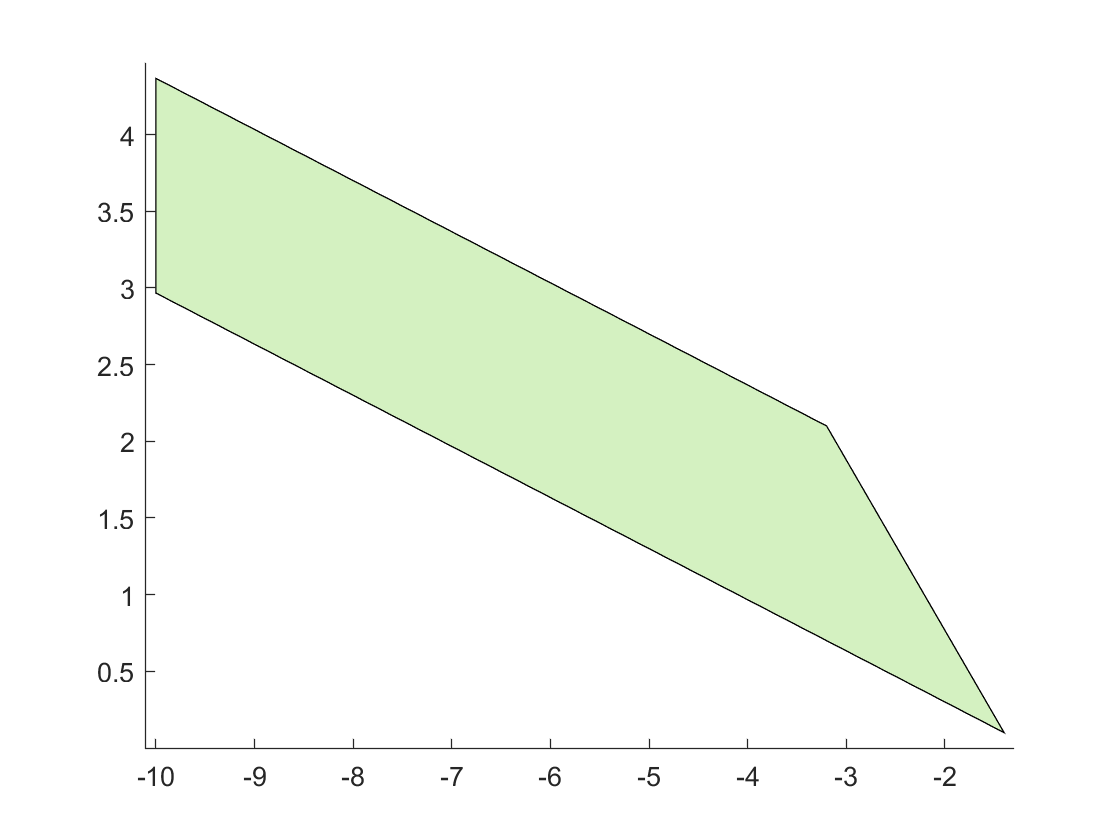

region(6).H = [G*region(6).E-S;inv(Gtild*inv(H)*Gtild')*(Stild+Gtild*inv(H)*F)];
region(6).K = [W-G*region(6).g;-inv(Gtild*inv(H)*Gtild')*Wtild];
lb = [-10;-10];
ub = [10,10];
figure
plotregion(-region(6).H,-region(6).K,lb,ub)
hold off

Set 7:

Gtild = G([1,4],:);
Wtild = W([1,4]);
Stild = zeros(2);
region(7).E = inv(H)*(Gtild'*inv(Gtild*inv(H)*Gtild')*(Stild+Gtild*inv(H)*F)-F);
region(7).g = inv(H)*Gtild'*inv(Gtild*inv(H)*Gtild')*Wtild;

What about the region? 

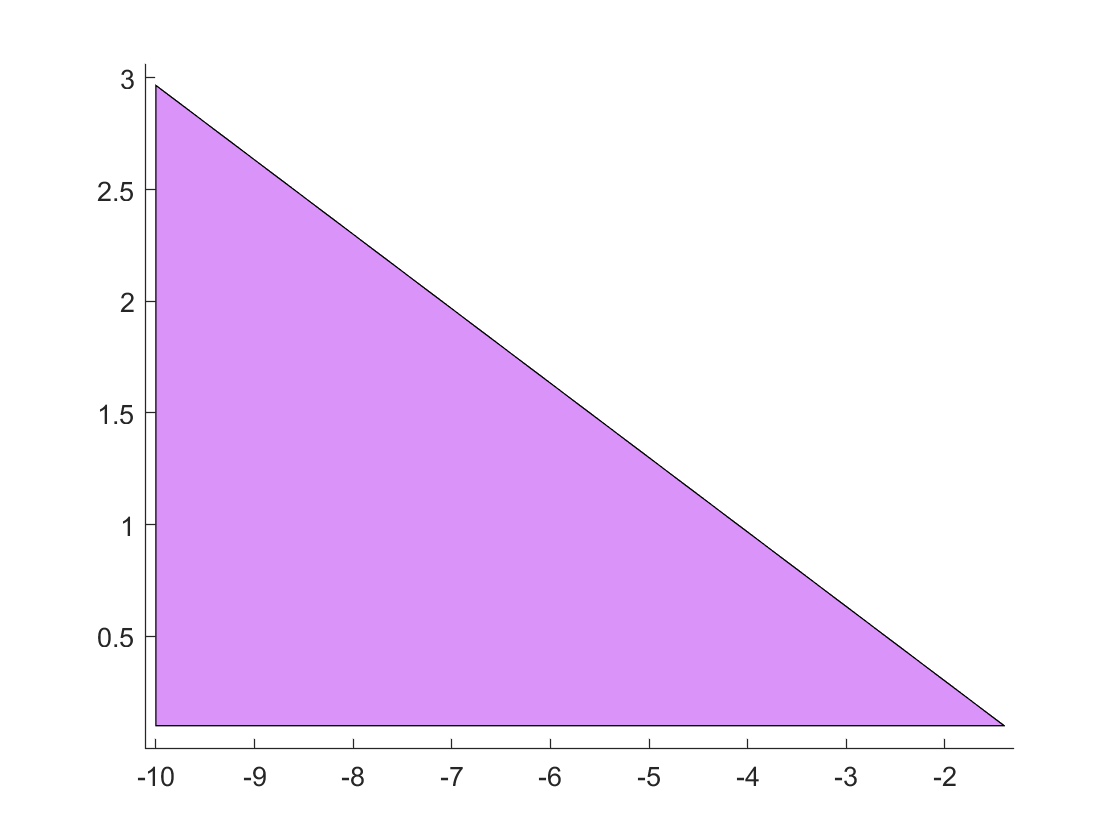

region(7).H = [G*region(7).E-S;inv(Gtild*inv(H)*Gtild')*(Stild+Gtild*inv(H)*F)];
region(7).K = [W-G*region(7).g;-inv(Gtild*inv(H)*Gtild')*Wtild];
lb = [-10;-10];
ub = [10,10];
figure
plotregion(-region(7).H,-region(7).K,lb,ub)
hold off

Set 8:

Gtild = G([2,3],:);
Wtild = W([2,3]);
Stild = zeros(2);
region(8).E = inv(H)*(Gtild'*inv(Gtild*inv(H)*Gtild')*(Stild+Gtild*inv(H)*F)-F);
region(8).g = inv(H)*Gtild'*inv(Gtild*inv(H)*Gtild')*Wtild;

What about the region? 

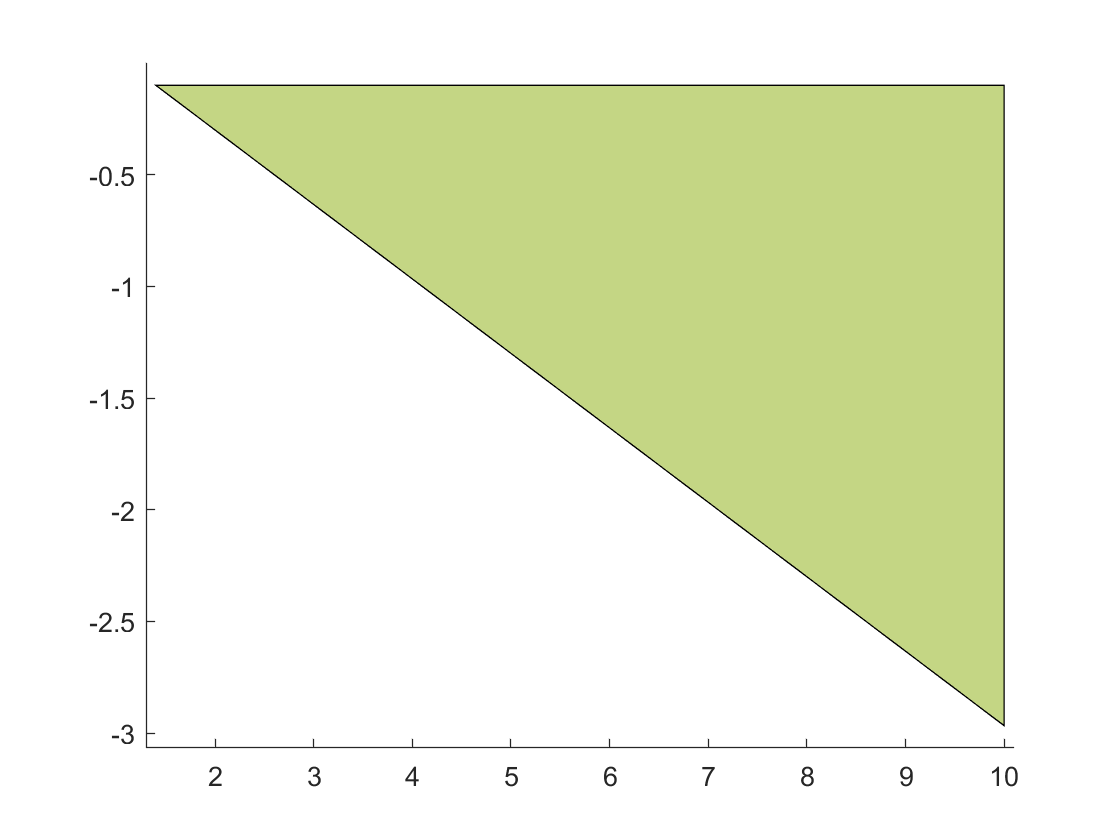

region(8).H = [G*region(8).E-S;inv(Gtild*inv(H)*Gtild')*(Stild+Gtild*inv(H)*F)];
region(8).K = [W-G*region(8).g;-inv(Gtild*inv(H)*Gtild')*Wtild];
lb = [-10;-10];
ub = [10,10];
figure
plotregion(-region(8).H,-region(8).K,lb,ub)
hold off

Unconstrained

If the problem is unconstrained, life gets a bit easier.  For the solution we have

region(9).E = -inv(H)*F;
region(9).g = zeros(2,1);

and the region is given by the constraints alone (no Lagrange multipliers) as

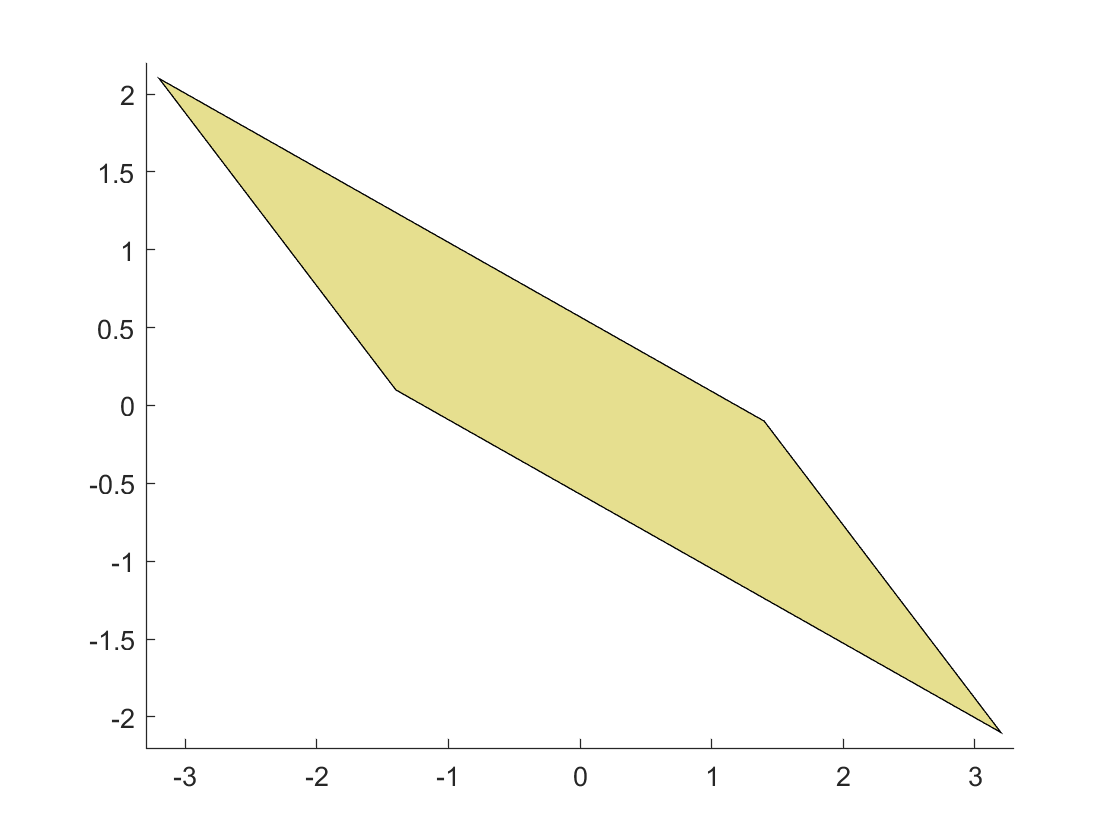

region(9).H = [G*region(9).E-S];
region(9).K = [W-G*region(9).g];
figure
plotregion(-region(9).H,-region(9).K,lb,ub)
hold off

Polyhedra

Let's now look at the partitioning of the state space.

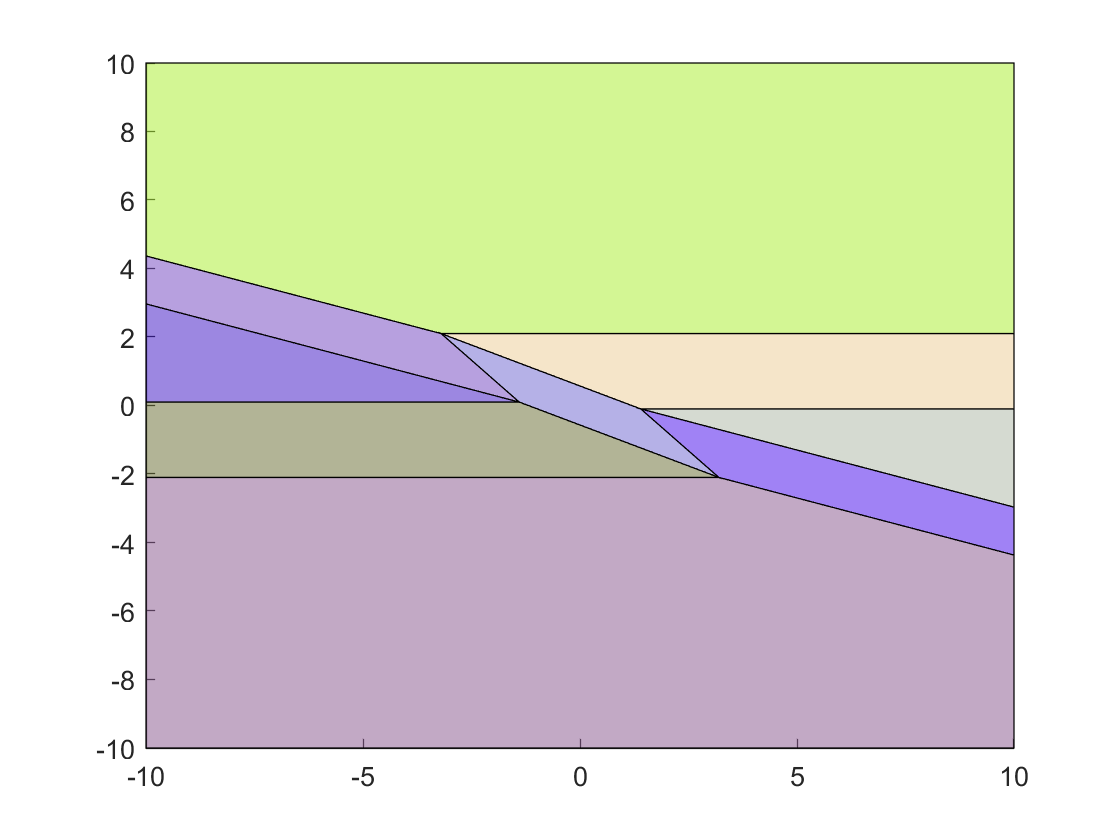

figure
plotregion(-region(1).H,-region(1).K,lb,ub)
plotregion(-region(2).H,-region(2).K,lb,ub)
plotregion(-region(3).H,-region(3).K,lb,ub)
plotregion(-region(4).H,-region(4).K,lb,ub)
plotregion(-region(5).H,-region(5).K,lb,ub)
plotregion(-region(6).H,-region(6).K,lb,ub)
plotregion(-region(7).H,-region(7).K,lb,ub)
plotregion(-region(8).H,-region(8).K,lb,ub)
plotregion(-region(9).H,-region(9).K,lb,ub)
ylim([lb(1),ub(1)])
xlim([lb(1),ub(1)])

The pre-computation is done.  Let's now compare the explicit and online solutions for a specific problem.

Setup the initial condition and run the approach for N steps (in this case, N seconds).  For sanity's sake, I'll also turn off the reporting that quadprog typically does.

X = [-1 ;2];
N = 40;
options = optimoptions('quadprog');
options.Display = 'none';
for ii = 1:N-1

The variable H is exactly what quadprog wants, but we have to modify the "f" argument to include the effects of the initial state.

    Xact(ii,:) = X; %For graphing
  %  f = F*X;

Solve the QP.

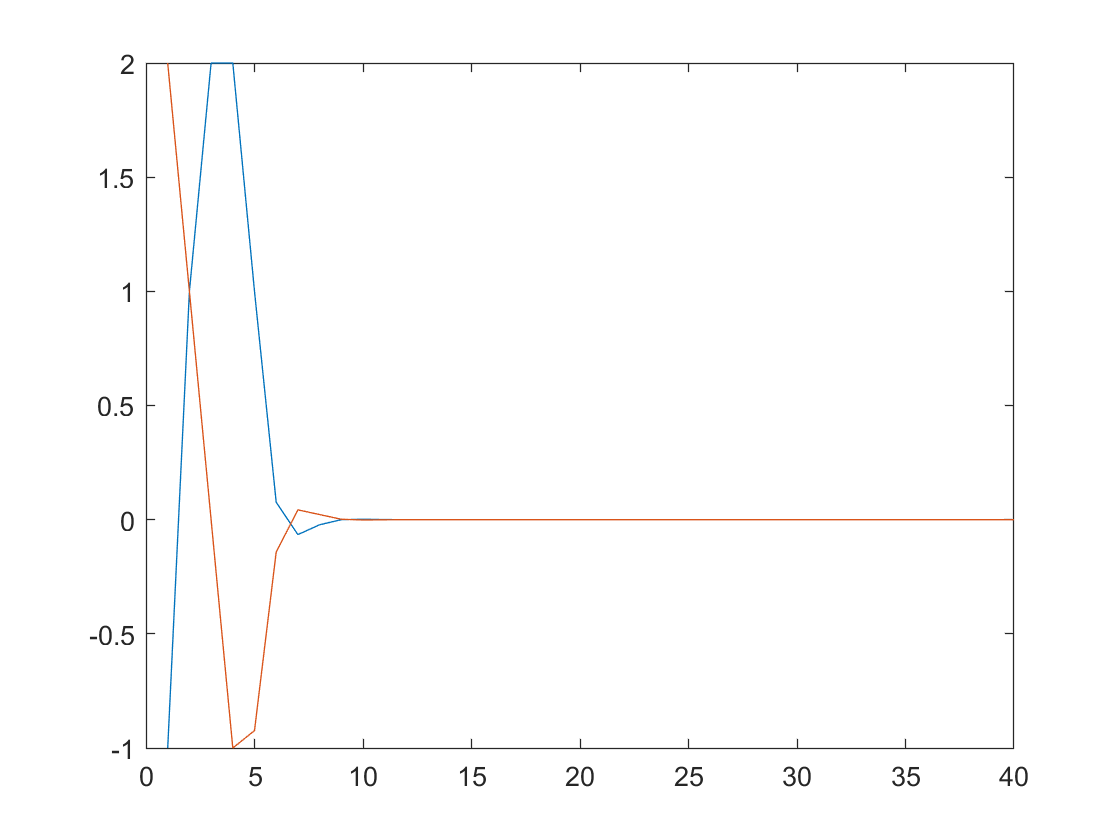

  %  [Z,~,~,~,lam] = quadprog(H,f,G,W+S*X,[],[],[],[],[],options);  %Here is the magic!
  for jj = 1:9

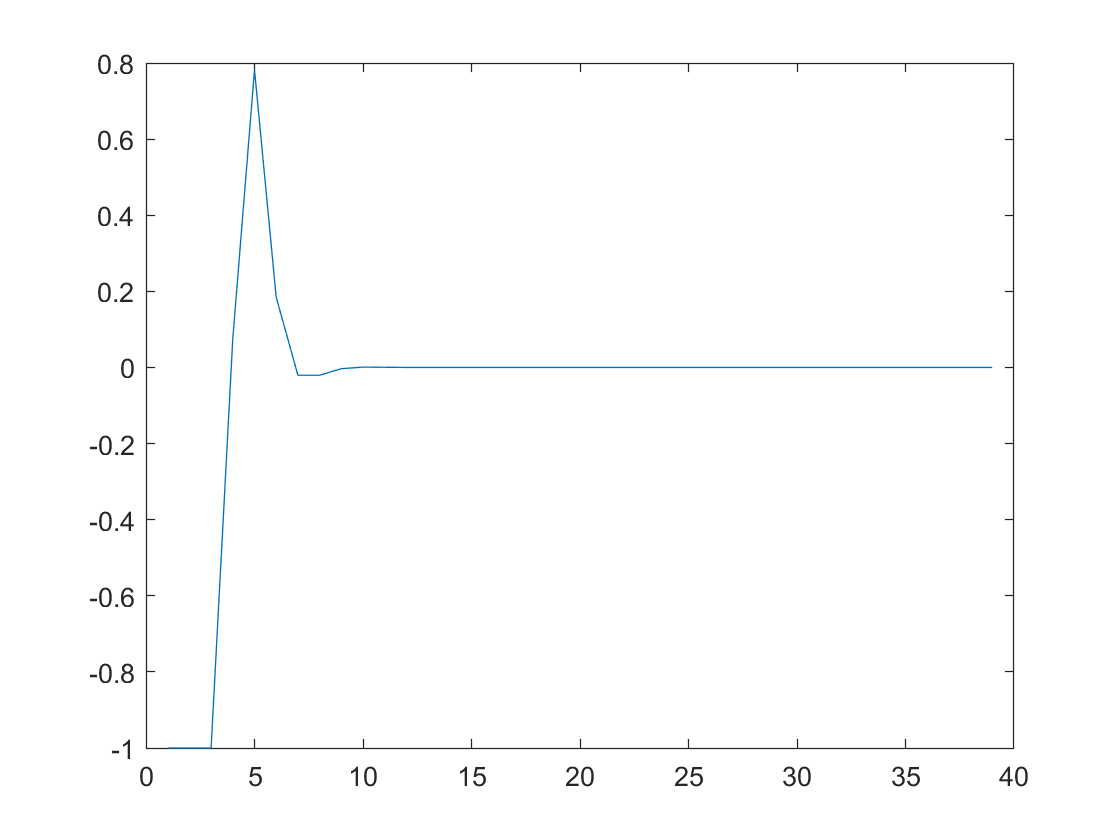

      if max(region(jj).H*X-region(jj).K)<=1e-5  %Give a little numerical slop

          Z = region(jj).E*X+region(jj).g;
          break;
      end
  end
    Uopt(ii) = Z(1);  %Just use the first item    

Now I'll apply the optimal control to the system.

    X = A*X+B*Z(1);
end
Xact(ii+1,:) = X;

Now let's see how well that worked.  It turns out that even with the tiny horizon (only 2 decision variables), it still worked OK.  We will soon talk about the relationship between prediction horizon and performance.

plot([1:N],Xact(:,1:2))
plot(Uopt)